Histogram estimated plant-specific k_max^vivo and kcat values from BRENDA

clear
load('Result2.mat','EC','kmax_vivo_light','best_row_ss_light','best_col_co_light','kcat_BRENDA_median');

kcat=readtable('Data/kcat_final_no_mutant.csv','Delimiter','\t'); % kcat BRENDA


kcat_BRENDA=[];
for i=1:length(EC)
    if isempty(find(strcmp(kcat.EC,EC(i))))
        if ~isempty(strfind(EC{i},'/'))
            EC_temp=strsplit(EC{i},'/');
            kcat_temp=[]; t_temp=[];
            for j=1:length(EC_temp)
                kcat_temp=[kcat_temp; kcat.kcat_1_sec(find(strcmp(kcat.EC,EC_temp(j))))];
                t_temp=[t_temp; kcat.tax_dist(find(strcmp(kcat.EC,EC_temp(j))))];
            end
            if ~isempty(kcat_temp)
                kcat_BRENDA = [kcat_BRENDA; kcat_temp(~isnan(kcat_temp))*60];
            end
        end
    end
end
[stat,P]=ttest2(kcat.kcat_1_sec(~isnan(kcat.kcat_1_sec)),(kmax_vivo_light{best_row_ss_light,best_col_co_light}(~isnan(kmax_vivo_light{best_row_ss_light,best_col_co_light}))))

stat = 0

P = 0.7844

median(kcat.kcat_1_sec(~isnan(kcat.kcat_1_sec)))

ans = 12.1100

median((kmax_vivo_light{best_row_ss_light,best_col_co_light}),'omitnan')

ans = 2.4378

std(kcat.kcat_1_sec(~isnan(kcat.kcat_1_sec)))

ans = 8.1871e+03

std((kmax_vivo_light{best_row_ss_light,best_col_co_light}),'omitnan')

ans = 2.7781e+03

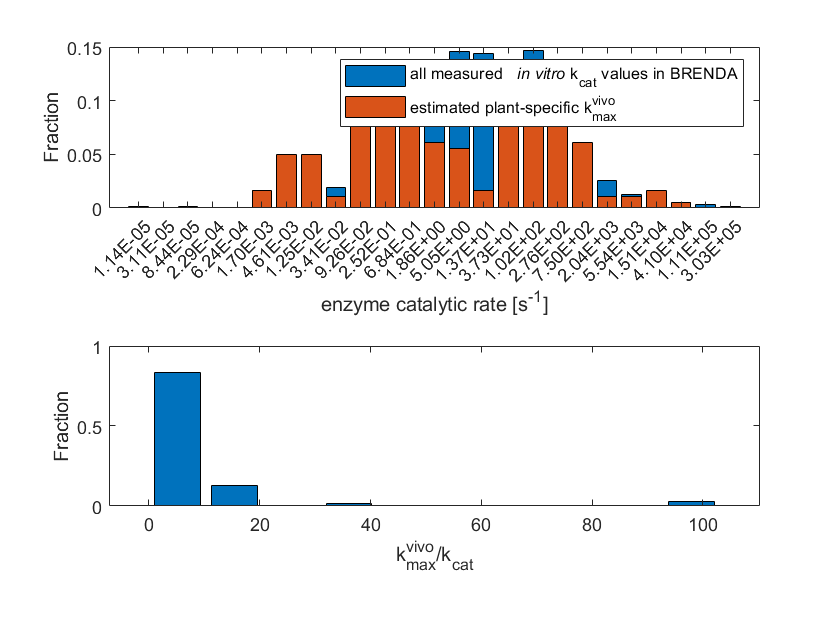


[n,edges] = histcounts([log(kcat.kcat_1_sec(~isnan(kcat.kcat_1_sec)));log(kmax_vivo_light{best_row_ss_light,best_col_co_light})]);
h2 = histcounts(log(kcat.kcat_1_sec(~isnan(kcat.kcat_1_sec))),'BinEdges', edges);
h1 = histcounts(log(kmax_vivo_light{best_row_ss_light,best_col_co_light}),'BinEdges', edges);

subplot(2,1,1)
bar(h2/sum(h2))
hold on 
bar(h1/sum(h1))
xlabel('enzyme catalytic rate [s^{-1}]')
ylabel('Fraction')
legend('all measured { \it in vitro} k_{cat} values in BRENDA','estimated plant-specific k_{max}^{vivo}')

for i=1:length(edges)-1
    E(i)=mean(exp(edges(i:i+1)));
end

Estr={'1.14E-05' '3.11E-05' '8.44E-05' '2.29E-04' '6.24E-04' '1.70E-03' '4.61E-03'...
   	'1.25E-02' '3.41E-02' '9.26E-02' '2.52E-01' '6.84E-01' '1.86E+00' '5.05E+00'...
   	'1.37E+01' '3.73E+01' '1.02E+02' '2.76E+02' '7.50E+02' '2.04E+03' '5.54E+03'...
   	'1.51E+04' '4.10E+04' '1.11E+05' '3.03E+05'};

set(gca,'XTick',1:length(E),'XTickLabel',Estr,'XTickLabelRotation',45)

subplot(2,1,2)
[H,b]=hist(kmax_vivo_light{best_row_ss_light,best_col_co_light}./kcat_BRENDA_median);

bar(b,H/sum(H))
ylabel('Fraction')
xlabel('k_{max}^{vivo}/k_{cat}')